A = [0 1; -2 -3]

A =      0     1
    -2    -3


B = [0 1]'

B =      0
     1


C = [-1 -3]

C =     -1    -3


D = 1

D = 1

tmax = 100

tmax = 100

syms s
simplify(C*(s*eye(size(A))-A)^-1*B +D)

$$ans = \frac{s^{2}+1}{s^{2}+3\,s+2}$$

[p,z] = pzmap(A,B,C,D)

p =     -1
    -2


z =    0.0000 + 1.0000i
   0.0000 - 1.0000i


t = linspace(0,tmax,2^12);
IC = [1 1]

IC =      1     1


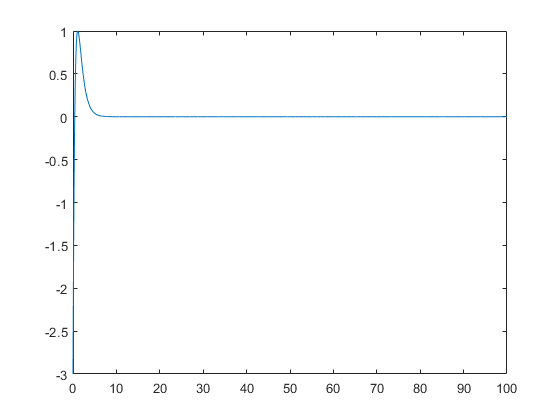

[t,x] = ode45(@(t,x) xfun(x,A,B,z(1),t),t,IC);
u = exp(z(1)*t); u = real(u) + imag(u);
y = -x(:,1) - 3*x(:,2) + u;
plot(t,y)

function dxdt = xfun(x,A,B,omega,t)
u = exp(omega*t); u = real(u) + imag(u);
dxdt = A*x + B*u;
end